# Build Manipulator Robot Using Denavit-Hartenberg Parameters

Use the Denavit-Hartenberg (DH) parameters of the Puma560® robot to build a robot. Each rigid body is added one at a time, with the child-to-parent transform specified by the joint object.

The DH parameters define the geometry of the robot with relation to how each rigid body is attached to its parent. For convenience, setup the parameters for the Puma560 robot in a matrix. The Puma robot is a serial chain manipulator. The DH parameters are relative to the previous line in the matrix, corresponding to the previous joint attachment. 

dhparams = [0   	pi/2	-.290   0;
            -.270	0       0       0;
            -.070	pi/2	0	0;
            0   	pi/2	.302	0;
            0          -pi/2	0   	0;
            0           0       .072    0];

Create a rigid body tree object to build the robot.

robot = robotics.RigidBodyTree;

Create the first rigid body and add it to the robot. To add a rigid body:

- Create a `RigidBody` object and give it a unique name.

- Create a `Joint` object and give it a unique name.

- Use `setFixedTransform` to specify the body-to-body transformation using DH parameters. The last element of the DH parameters, `theta`, is ignored because the angle is dependent on the joint position.

- Call `addBody` to attach the first body joint to the base frame of the robot.

body1 = robotics.RigidBody('body1');
jnt1 = robotics.Joint('jnt1','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')

Create and add other rigid bodies to the robot. Specify the previous body name when calling `addBody` to attach it. Each fixed transform is relative to the previous joint coordinate frame.

body2 = robotics.RigidBody('body2');
jnt2 = robotics.Joint('jnt2','revolute');
body3 = robotics.RigidBody('body3');
jnt3 = robotics.Joint('jnt3','revolute');
body4 = robotics.RigidBody('body4');
jnt4 = robotics.Joint('jnt4','revolute');
body5 = robotics.RigidBody('body5');
jnt5 = robotics.Joint('jnt5','revolute');
body6 = robotics.RigidBody('body6');
jnt6 = robotics.Joint('jnt6','revolute');

setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');
setFixedTransform(jnt6,dhparams(6,:),'dh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')

Verify that your robot was built properly by using the `showdetails` or `show` function. `showdetails` lists all the bodies in the MATLAB® command window. `show` displays the robot with a given configuration (home by default). Calls to `axis` modify the axis limits and hide the axis labels.

showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


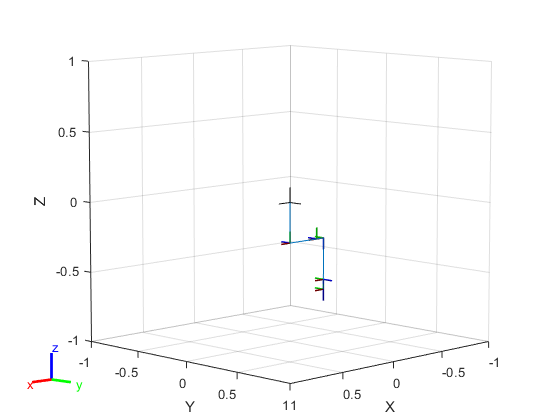


show(robot);
%axis([-0.5,0.5,-0.5,0.5,-0.5,0.5])
axis on

*Copyright 2012 The MathWorks, Inc.*